%Parámetros DH
ai = [0, -97.4, 98.2, 0];
alphai = [round(-pi/2,2), 0, 0, round(-pi/2,2)];
%alphai = [deg2rad(-90), 0, 0, deg2rad(-90)];
di = [0, 0, 0, 0];
thetai = {'q1*', 'q2*', 'q3*', 'q4*'};
offset = [0, round(pi/2,2), round(-pi/2,2), round(-pi/2,2)];
%offset = [0, deg2rad(90), deg2rad(-90), deg2rad(-90)];
table(ai',alphai',di',thetai',offset','VariableNames',{'a (mm)','alpha (rad)','d (mm)','theta (rad)', 'Offset (°)'})

ans = 4×5 table
    a (mm)    alpha (rad)    d (mm)    theta (rad)    Offset (°)
    ______    ___________    ______    ___________    __________

        0        -1.57         0         {'q1*'}            0   
    -97.4            0         0         {'q2*'}         1.57   
     98.2            0         0         {'q3*'}        -1.57   
        0        -1.57         0         {'q4*'}        -1.57   


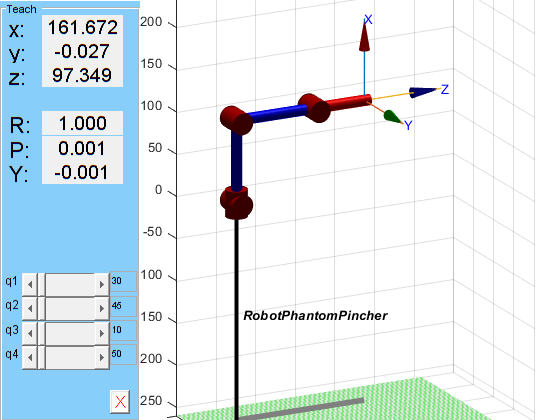

%Diagrama Robot
L(1) = Link('revolute','alpha',alphai(1),'a',ai(1),'d',di(1),'offset',offset(1),'qlim',[deg2rad(30) deg2rad(230)]);
L(2) = Link('revolute','alpha',alphai(2),'a',ai(2),'d',di(2),'offset',offset(2),'qlim',[deg2rad(45) deg2rad(255)]);
L(3) = Link('revolute','alpha',alphai(3),'a',ai(3),'d',di(3),'offset',offset(3),'qlim',[deg2rad(10) deg2rad(280)]);
L(4) = Link('revolute','alpha',alphai(4),'a',ai(4),'d',di(4),'offset',offset(4),'qlim',[deg2rad(50) deg2rad(240)]);
Tool = [1 0 0 0; 0 1 0 0; 0 0 1 63.55; 0 0 0 1];
World = eye(4);
RobotPhantom = SerialLink(L,'name','RobotPhantomPincher','tool',Tool,'base',World);
RobotPhantom.plot([0 0 0 0],'view',[-27 18]);
axis([-50 300 -150 50 -260 250]);
RobotPhantom.teach();

%Cinemática del robot
syms q1 q2 q3 q4 real
A01 = trotz(q1) * transl(0,0,di(1)) * transl(ai(1),0,0) * round(trotx(alphai(1)),2)

$$A01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12 = trotz(q2) * transl(0,0,di(2)) * transl(ai(2),0,0) * round(trotx(alphai(2)),2)

$$A12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & -\frac{487\,\cos\left(q_{2}\right)}{5}\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & -\frac{487\,\sin\left(q_{2}\right)}{5}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A23 = trotz(q3) * transl(0,0,di(3)) * transl(ai(3),0,0) * round(trotx(alphai(3)),2)

$$A23 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & \frac{491\,\cos\left(q_{3}\right)}{5}\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & \frac{491\,\sin\left(q_{3}\right)}{5}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A34 = trotz(q4) * transl(0,0,di(4)) * transl(ai(4),0,0) * round(trotx(alphai(4)),2)

$$A34 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & 0 & -\sin\left(q_{4}\right) & 0\\ \sin\left(q_{4}\right) & 0 & \cos\left(q_{4}\right) & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

MTH04 = simplify(A01 * A12 * A23 * A34) %Cinemática directa del robot.

$$MTH04 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right) & -\sigma_{2}\,\cos\left(q_{1}\right) & \frac{\cos\left(q_{1}\right)\,\sigma_{1}}{5}\\ \sigma_{3}\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right) & -\sigma_{2}\,\sin\left(q_{1}\right) & \frac{\sin\left(q_{1}\right)\,\sigma_{1}}{5}\\ -\sigma_{2} & 0 & -\sigma_{3} & \frac{487\,\sin\left(q_{2}\right)}{5}-\frac{491\,\sin\left(q_{2}+q_{3}\right)}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=491\,\cos\left(q_{2}+q_{3}\right)-487\,\cos\left(q_{2}\right)\\ \sigma_{2}=\sin\left(q_{2}+q_{3}+q_{4}\right)\\ \sigma_{3}=\cos\left(q_{2}+q_{3}+q_{4}\right) \end{array}$$

%Posiciones del robot (Punto 1)

% RobotPhantom.plot([0 0 0 0],'view',[-20 20]); %Posición Home
% axis([-50 300 -150 50 -260 250]);

% RobotPhantom.plot([1 0 0 0],'view',[-20 20]); %Posición 1
% axis([-50 300 -150 250 -260 250]);

% RobotPhantom.plot([0 1 0 0],'view',[-20 20]); %Posición 2
% axis([-50 300 -150 50 -260 250]);

% RobotPhantom.plot([0 0 1 0],'view',[-20 20]); %Posición 3
% axis([-50 300 -150 50 -260 250]);

% RobotPhantom.plot([0 0 0 1],'view',[-20 20]); %Posición 4
% axis([-50 300 -150 50 -260 250]);

% Posiciones del robot (Punto 2)

% L(1) = Link('revolute','alpha',alphai(1),'a',ai(1),'d',di(1),'offset',offset(1),'qlim',[deg2rad(30) deg2rad(230)]);
% L(2) = Link('revolute','alpha',alphai(2),'a',ai(2),'d',di(2),'offset',offset(2),'qlim',[deg2rad(45) deg2rad(255)]);
% L(3) = Link('revolute','alpha',alphai(3),'a',ai(3),'d',di(3),'offset',offset(3),'qlim',[deg2rad(10) deg2rad(280)]);
% L(4) = Link('revolute','alpha',alphai(4),'a',ai(4),'d',di(4),'offset',offset(4),'qlim',[deg2rad(50) deg2rad(240)]);
% Tool = [1 0 0 0; 0 1 0 0; 0 0 1 63.55; 0 0 0 1];
% World = eye(4);
% RobotPhantom = SerialLink(L,'name','RobotPhantomPincher','tool',Tool,'base',World); %Posición Home
% RobotPhantom.plot([deg2rad(q1) deg2rad(q2) deg2rad(q3) deg2rad(q4)],'view',[-30 20]);
% axis([-100 350 -150 100 -270 220]);

% L(1) = Link('revolute','alpha',alphai(1),'a',ai(1),'d',di(1),'offset',offset(1),'qlim',[deg2rad(30) deg2rad(230)]);
% L(2) = Link('revolute','alpha',alphai(2),'a',ai(2),'d',di(2),'offset',offset(2),'qlim',[deg2rad(45) deg2rad(255)]);
% L(3) = Link('revolute','alpha',alphai(3),'a',ai(3),'d',di(3),'offset',offset(3),'qlim',[deg2rad(10) deg2rad(280)]);
% L(4) = Link('revolute','alpha',alphai(4),'a',ai(4),'d',di(4),'offset',offset(4),'qlim',[deg2rad(50) deg2rad(240)]);
% Tool = [1 0 0 0; 0 1 0 0; 0 0 1 63.55; 0 0 0 1];
% World = eye(4);
% RobotPhantom = SerialLink(L,'name','RobotPhantomPincher','tool',Tool,'base',World); %Posición 2
% RobotPhantom.plot([deg2rad(q1) deg2rad(q2) deg2rad(q3) deg2rad(q4)],'view',[-30 20]);
% axis([-100 250 -100 100 -260 130]);

% L(1) = Link('revolute','alpha',alphai(1),'a',ai(1),'d',di(1),'offset',offset(1),'qlim',[deg2rad(30) deg2rad(230)]);
% L(2) = Link('revolute','alpha',alphai(2),'a',ai(2),'d',di(2),'offset',offset(2),'qlim',[deg2rad(45) deg2rad(255)]);
% L(3) = Link('revolute','alpha',alphai(3),'a',ai(3),'d',di(3),'offset',offset(3),'qlim',[deg2rad(10) deg2rad(280)]);
% L(4) = Link('revolute','alpha',alphai(4),'a',ai(4),'d',di(4),'offset',offset(4),'qlim',[deg2rad(50) deg2rad(240)]);
% Tool = [1 0 0 0; 0 1 0 0; 0 0 1 63.55; 0 0 0 1];
% World = eye(4);
% RobotPhantom = SerialLink(L,'name','RobotPhantomPincher','tool',Tool,'base',World); %Posición 3
% RobotPhantom.plot([deg2rad(q1) deg2rad(q2) deg2rad(q3) deg2rad(q4)],'view',[-30 20]);
% axis([-100 350 -200 100 -270 100]);

% L(1) = Link('revolute','alpha',alphai(1),'a',ai(1),'d',di(1),'offset',offset(1),'qlim',[deg2rad(30) deg2rad(230)]);
% L(2) = Link('revolute','alpha',alphai(2),'a',ai(2),'d',di(2),'offset',offset(2),'qlim',[deg2rad(45) deg2rad(255)]);
% L(3) = Link('revolute','alpha',alphai(3),'a',ai(3),'d',di(3),'offset',offset(3),'qlim',[deg2rad(10) deg2rad(280)]);
% L(4) = Link('revolute','alpha',alphai(4),'a',ai(4),'d',di(4),'offset',offset(4),'qlim',[deg2rad(50) deg2rad(240)]);
% Tool = [1 0 0 0; 0 1 0 0; 0 0 1 63.55; 0 0 0 1];
% World = eye(4);
% RobotPhantom = SerialLink(L,'name','RobotPhantomPincher','tool',Tool,'base',World); %Posición 4
% RobotPhantom.plot([deg2rad(q1) deg2rad(q2) deg2rad(q3) deg2rad(q4)],'view',[-30 20]);
% axis([-100 150 -150 300 -260 170]);

% L(1) = Link('revolute','alpha',alphai(1),'a',ai(1),'d',di(1),'offset',offset(1),'qlim',[deg2rad(30) deg2rad(230)]);
% L(2) = Link('revolute','alpha',alphai(2),'a',ai(2),'d',di(2),'offset',offset(2),'qlim',[deg2rad(45) deg2rad(255)]);
% L(3) = Link('revolute','alpha',alphai(3),'a',ai(3),'d',di(3),'offset',offset(3),'qlim',[deg2rad(10) deg2rad(280)]);
% L(4) = Link('revolute','alpha',alphai(4),'a',ai(4),'d',di(4),'offset',offset(4),'qlim',[deg2rad(50) deg2rad(240)]);
% Tool = [1 0 0 0; 0 1 0 0; 0 0 1 63.55; 0 0 0 1];
% World = eye(4);
% RobotPhantom = SerialLink(L,'name','RobotPhantomPincher','tool',Tool,'base',World); %Posición 5
% RobotPhantom.plot([deg2rad(q1) deg2rad(q2) deg2rad(q3) deg2rad(q4)],'view',[-30 20]);
% axis([-100 150 -250 200 -260 320]);